TOPGO=readtable('TOP10report_intersection.xlsx', 'Sheet',1); % read top 10 terms of GO and KEGG.
TOPKEGG=readtable('TOP10report_intersection.xlsx', 'Sheet', 2);
disp(TOPGO(1:2,1:end))

                Name                Count     p_value  
    ____________________________    _____    __________

    {'adaptive immune response'}      9      0.00080954
    {'cell adhesion'           }      7        0.041582



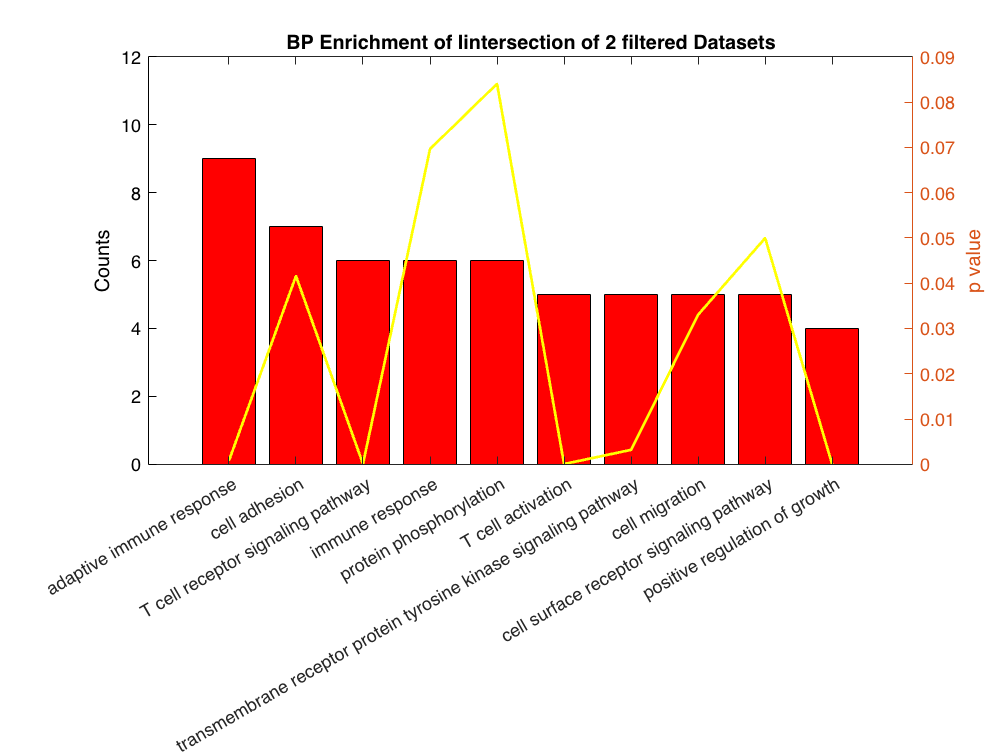

GOnames=TOPGO{:,1}'; % indexing GO names.
loc = [1:10]; % for line plot. 

% plot BP
figure(1)
X1=categorical(GOnames(1:10));
bar(TOPGO{1:10,2},'r')
set(gca,'XTickLabel',X1)
ylim([0 12])
ylabel('Counts')
title('BP Enrichment of Iintersection of 2 filtered Datasets')
hold on

yyaxis right
ylabel('p value')
plot(loc, TOPGO{1:10,3},'y', 'LineWidth',1.5)

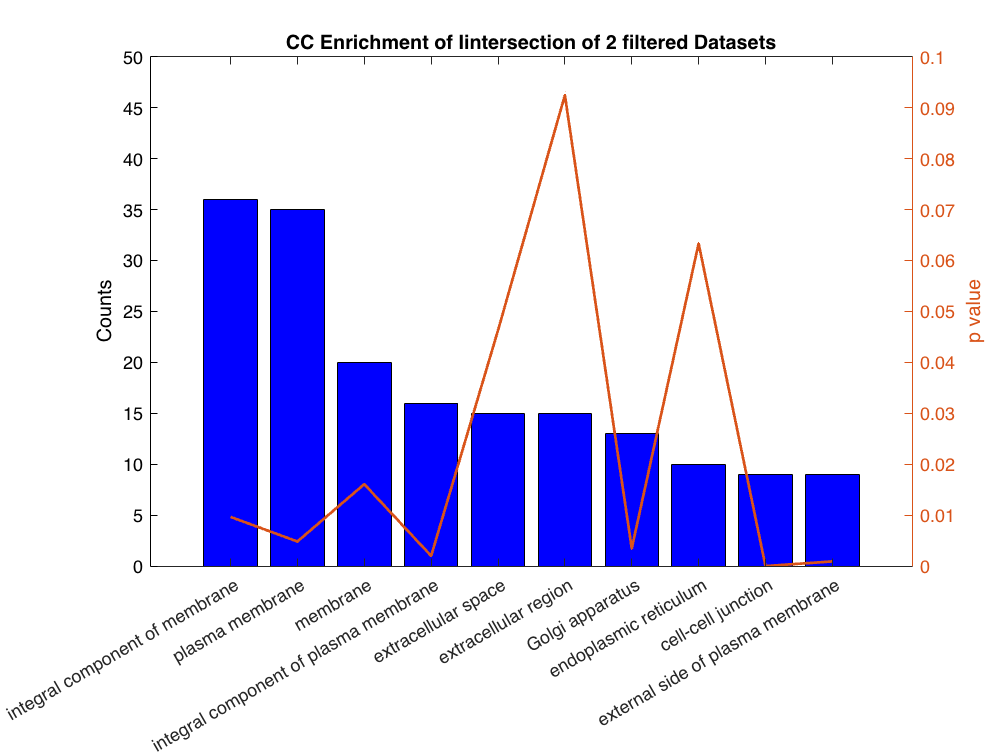



figure(2)
% plot CC
X2=categorical(GOnames(11:20));
bar(TOPGO{11:20,2},'b')
set(gca,'XTickLabel',X2)
ylim([0 50])
ylabel('Counts')
title('CC Enrichment of Iintersection of 2 filtered Datasets')
hold on

yyaxis right
ylabel('p value')
plot(loc, TOPGO{11:20,3}, 'LineWidth',1.5)

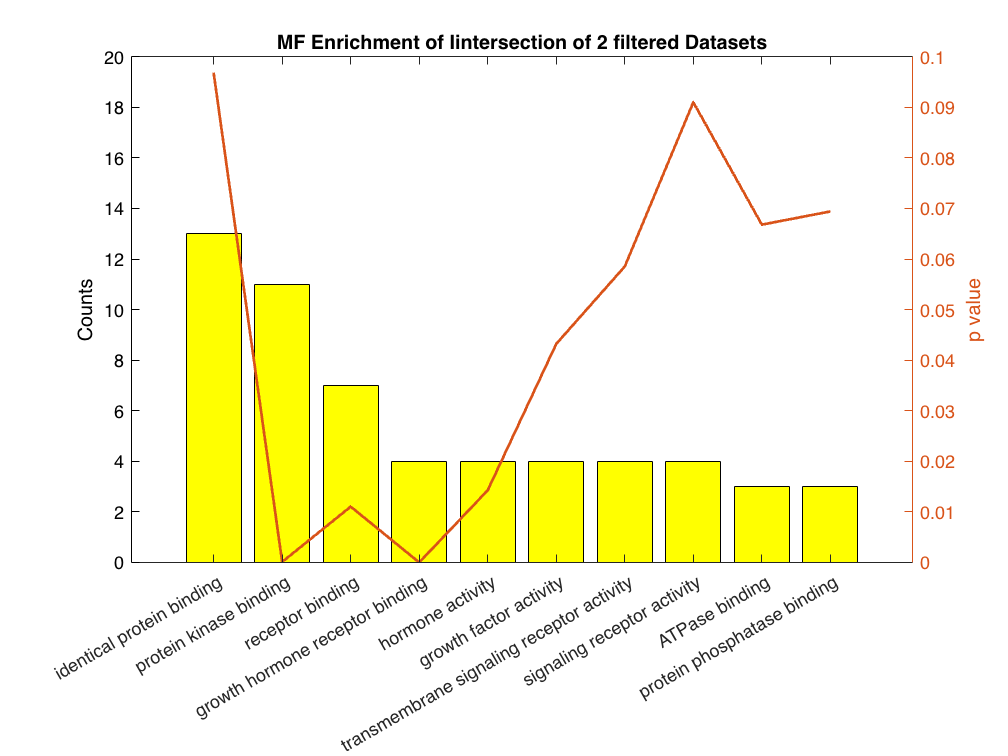


figure(3)
% plot MF
X3=categorical(GOnames(21:end));
bar(TOPGO{21:end,2},'y')
set(gca,'XTickLabel',X3)
ylim([0 20])
ylabel('Counts')
title('MF Enrichment of Iintersection of 2 filtered Datasets')
hold on

yyaxis right
ylabel('p value')
plot(loc, TOPGO{21:end,3}, 'LineWidth',1.5)

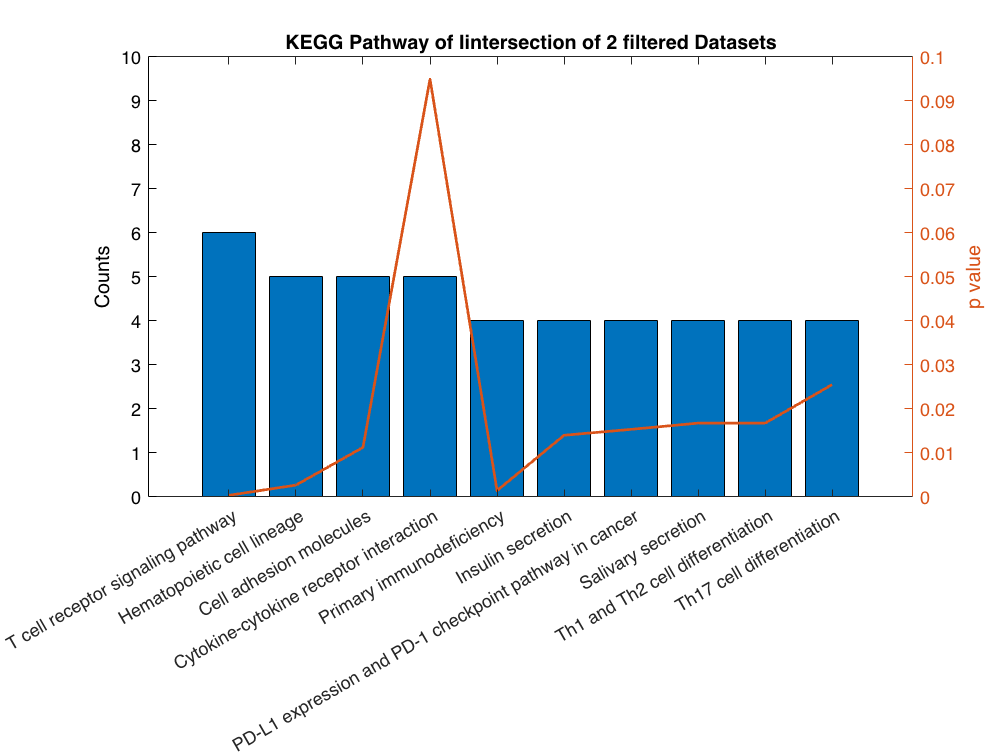

figure(4)
% plot KEGG pathway
X4=categorical(TOPKEGG{:,1});
bar(TOPKEGG{:,2})
set(gca,'XTickLabel',X4)
ylim([0 10])
ylabel('Counts')
title('KEGG Pathway of Iintersection of 2 filtered Datasets')
hold on

yyaxis right
ylabel('p value')
plot(loc, TOPKEGG{:,3}, 'LineWidth',1.5)